**Multiobjective Optimization. Nonlinear problem. Scalarization method.**


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & \left(x_1^2 +x_2^2 +2x_1 -2x_2 \right),\left(x_1^2 +x_2^2 -6x_1 -4x_2 \right)\\
\mathrm{subject}\;\mathrm{to} & -x_2 \le 0\\
\; & -2x_1 +x_2 \le 0\\
\; & 2x_1 +x_2 \le 4
\end{array}\right.$$


Find the set of minima and weak minima by means of the scalarization method.

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

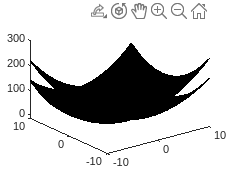

% Plot of data 
x1 = -10:0.1:10;
x2 = -10:0.1:10;


[X1,X2] = meshgrid(x1,x2);

X3 = X1.^2 + X2.^2 + 2.*X1 - 4.*X2;
X4 = X1.^2 + X2.^2 - 6.*X1 - 4.*X2;

surface(X1,X2,X3);
hold on
surface(X1,X2,X4);
view(3);
hold off

% Check convexity
Q1 = [2 0
      0 2];

f1 = [2
     -4];

Q2 = [2 0
      0 2];

f2 = [-6
      -4];

eigenvalue_1 = eig(Q1)

eigenvalue_1 =      2
     2


eigenvalue_2 = eig(Q1)

eigenvalue_2 =      2
     2


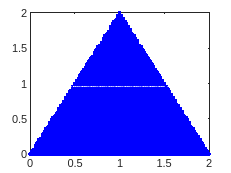

% Feasible region
x1 = -10:0.02:10;
x2 = -10:0.02:10;


[X1,X2] = meshgrid(x1,x2);

condition_x1 = X1((-X2<=0) & (-2.*X1 + X2<=0) & (2.*X1+X2<=4));
condition_x2 = X2((-X2<=0) & (-2.*X1 + X2<=0) & (2.*X1+X2<=4));

plot(condition_x1, condition_x2, 'b.');

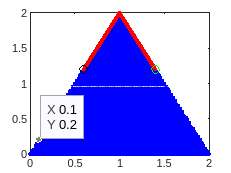

% Set the environment values
A = [0 -1
    -2  1
     2  1];

b = [0
     0
     4];

% Set the problem
options = optimset('Display', 'off');

hold on
for alpha = 0.001:0.001:0.999
    f = [8*alpha-6
         -4];
    x = quadprog(Q1,f, A, b, [], [], [], [], [], options);
    plot(x(1), x(2), 'r.');
end

% Extreme alpha
% alpha = 0;
x0 = quadprog(Q2, f2, A, b, [], [], [], [], [], options);
plot(x0(1), x0(2), 'go');

%alpha = 1;
x1 = quadprog(Q1, f1, A, b, [], [], [], [], [], options);
plot(x1(1), x1(2), 'ko');

hold off